## FFT/DTFT

### Intro

### A)

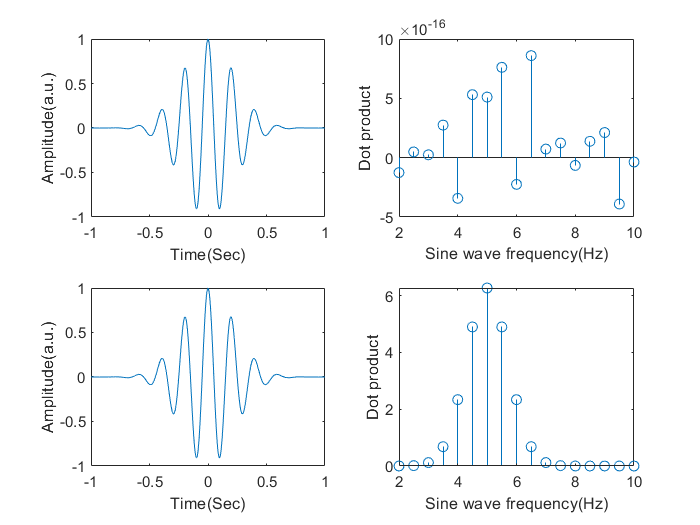

clear all

sampling_rate = 1000;
tmin = -1;
tmax = 1;
theta = pi/2;
t_values = tmin:(1/sampling_rate):tmax;
f_values = (2:0.5:10);

x = sin(10*pi.*t_values + theta) .* exp((-t_values.^2)/0.1);
y1 = [];
y2 = [];
for f=f_values
    y1(end+1) = dot(x, sin(2*pi*f.*t_values) ./ norm(sin(2*pi*f.*t_values)));
    y2(end+1) = dot(x, exp(1i*2*pi*f.*t_values) ./ norm(exp(1i*2*pi*f.*t_values)));
end

figure

subplot(2,2,1)
plot(t_values, x)
xlabel('Time(Sec)')
ylabel('Amplitude(a.u.)')

subplot(2,2,2)
stem(f_values, y1)
xlabel('Sine wave frequency(Hz)')
ylabel('Dot product')

subplot(2,2,3)
plot(t_values, x)
xlabel('Time(Sec)')
ylabel('Amplitude(a.u.)')

subplot(2,2,4)
stem(f_values, abs(y2))
xlabel('Sine wave frequency(Hz)')
ylabel('Dot product')

### B)

It gives Fourier series coefficient of signal x(t) without correcting coefficients.

### C)

With sin(t) we can not have good scale in frequency part of x(t). Dot with sin(t), it restricted in [-1 1].

### Exercise

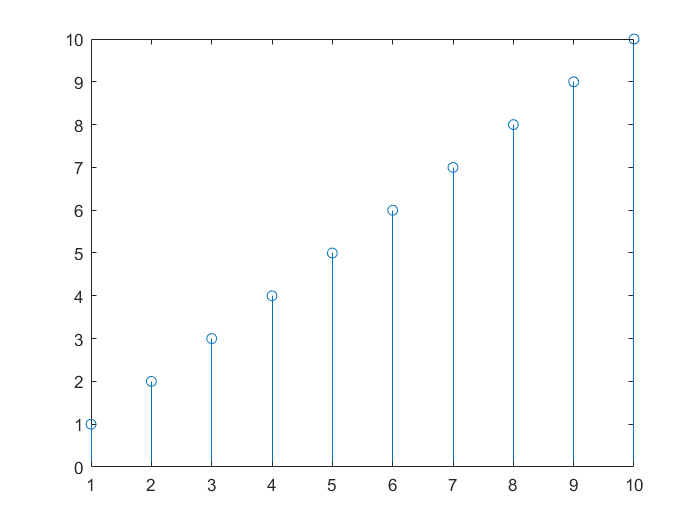

clear all
array = 1:10;
shifted_array = fftshift(array);

figure
stem(array)

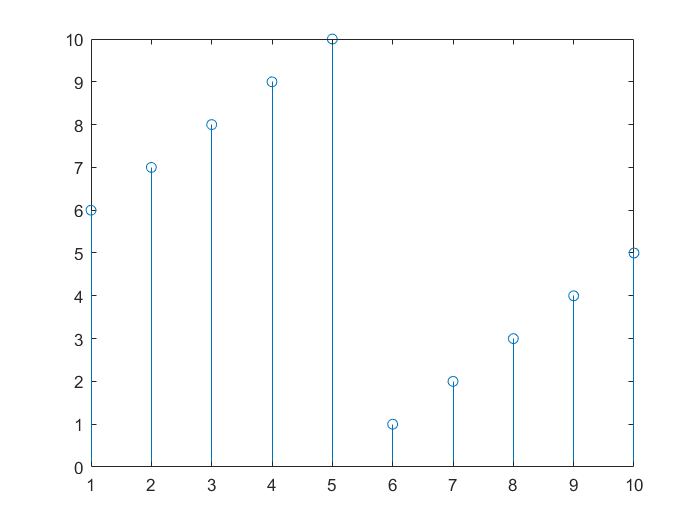

stem(shifted_array)

### Implementation:

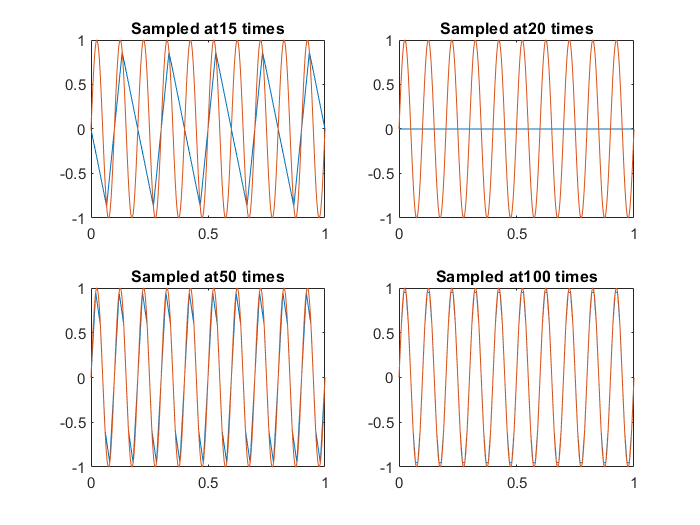

clear all

sampling_rate = 1000;
tmin = 0;
tmax = 1;
t_values = tmin:(1/sampling_rate):tmax;
f = 10;


x = sin(2*pi*f.*t_values);

figure

sampling_rates = [15 20 50 100];
for i=1:length(sampling_rates)
    subplot(2,2,i)
    curr_t_values = tmin:(1/sampling_rates(i)):tmax;
    plot(curr_t_values, sin(2*pi*f.*curr_t_values))
    title(strcat('Sampled at', num2str(sampling_rates(i)),' times'))
    hold on
    plot(t_values, x)
    hold off
end

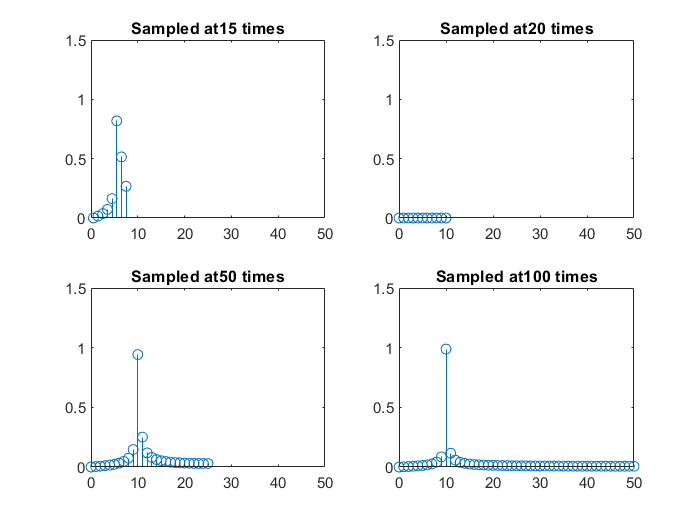


figure

for i=1:length(sampling_rates)
    subplot(2,2,i)
    curr_t_values = tmin:(1/sampling_rates(i)):tmax;
    X = fft(x);
    
    curr_npts = (tmax-tmin)*sampling_rates(i) + 1;
    f_shifted_values = linspace(-sampling_rates(i)/2, sampling_rates(i)/2, curr_npts);
    stem(f_shifted_values, 2*fftshift(abs(fft(sin(2*pi*f.*curr_t_values))))/sampling_rates(i))
    title(strcat('Sampled at', num2str(sampling_rates(i)),' times'))
    xlim([0 50])
    ylim([0 1.5])
end

### B)

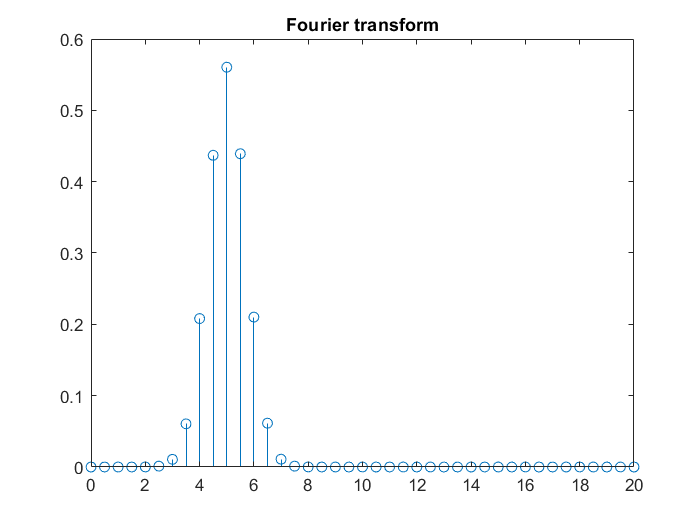

clear all

sampling_rate = 1000;
tmin = -1;
tmax = 1;
theta = pi/2;
npts = (tmax-tmin)*sampling_rate + 1;
t_values = tmin:(1/sampling_rate):tmax;
f_values = 1:npts;
tf = (0:npts-1)/npts;

x = sin(10*pi.*t_values + theta) .* exp((-t_values.^2)/0.1);
X = [];
for f=f_values
    X(end+1) = dot(x, exp(-1i*2*pi*(f-1)*tf));
end

figure
f_shifted_values = linspace(-sampling_rate/2, sampling_rate/2, npts);
stem(f_shifted_values, 2*fftshift(abs(X))/sampling_rate)
title('Fourier transform')
xlim([0 20])

### C)

It is working with the first and second coefficients correctly and you can compare the manual implementation and with fft function below.

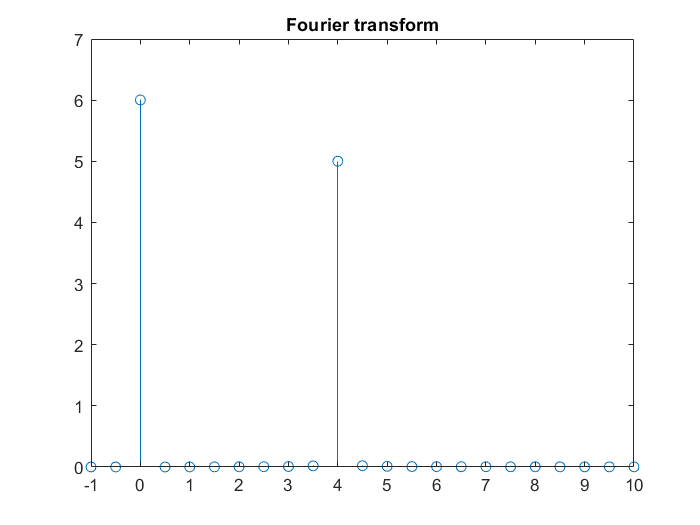

clear all

sampling_rate = 1000;
tmin = -1;
tmax = 1;
theta = pi/2;
npts = (tmax-tmin)*sampling_rate + 1;
t_values = tmin:(1/sampling_rate):tmax;
f_values = 1:npts;
tf = (0:npts-1)/npts;

x = 1.5 + 2.5*sin(8*pi.*t_values);
X = [];
for f=f_values
    X(end+1) = dot(x, exp(-1i*2*pi*(f-1)*tf));
end

figure
f_shifted_values = linspace(-sampling_rate/2, sampling_rate/2, npts);
stem(f_shifted_values, 2*fftshift(abs(X))/sampling_rate)
title('Fourier transform')
xlim([-1 10])

stem(f_shifted_values, 2*fftshift(abs(fft(x)))/sampling_rate)
title('Fourier transform')
xlim([-1 10])